# s_oeBloodFluorophoreTongueSrch 

The notes are in s_oeBloodFluorophoreLipSrch.mlx.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;

## Create fluorophore matrix and read database 

We create the base fluorophore emissions matrix.  It does not include blood (fluorophoresB).  Below, we sweep through different potential levels of blood optical density, checking how well the modified fluorophore matrix predicts the data samples.  Notice that the effective optical density of blood can depend on the wavelength of the excitation light.  Some lights will penetrate into the skin (substrate) more deeply than others, thus creating a longer path through the blood.

We tried many fluorophore files from the literature. These are described in in **s_oeFluorophoreEmissions.mlx**.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

**Things we tried.**

- fluorophoreNames = {'collagen1','FAD_webfluor'}; -  Not enough dimensions. Fails to fit the data closely.

- fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'}; - Never chooses elastin

- fluorophoreNames = {'collagen1','FAD_webfluor','KeratinValdez'}; - Replaced NADH with Keratin.  Removed elastin. Too flat around 540, and a deep dive around 580.  General slope is OK.

- fluorophoreNames = {'collagen1','KeratinValdez','FADValdez'}; - Way off. Doesn't even get an OK fit of the blood.

- fluorophoreNames = {'CollagenWuQu','FADLin'}; - Way off, as above. Fails with blood

- fluorophoreNames = {'CollagenWuQu','FADValdez'}; - Way off as above.

- fluorophoreNames = {'CollagenWuQu','FAD_webfluor'}; - FIt is bad, but the blood is OK.

- fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'}; - Another blood miss.

- fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'}; - This collagen is goofy, and the fits are bad including the blood.

We should try a few more examples with Keratin.

**Our winners so far**

- fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'}; - Best fit so far.  

- fluorophoreNames = {'collagen1','NADH_webfluor','FADLin'}; - Still good if we swap collagen1 for ColalgenWuQu.  That's a good thing.  

We should also try deoxygenated blood at some point, by adding in a collagen-deoxy column.

fluorophoreNames = {'collagen1','NADH_webfluor','FADLin'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNames,'wave',wave);

## 405/415 nm excitation

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
odError = zeros(numel(odLevels),numel(subjects));  
ods = zeros(numel(subjects),1);    

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNames,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 24.00
OD across subjects for 405/415nm 21.00
OD across subjects for 405/415nm 22.00
OD across subjects for 405/415nm 25.00


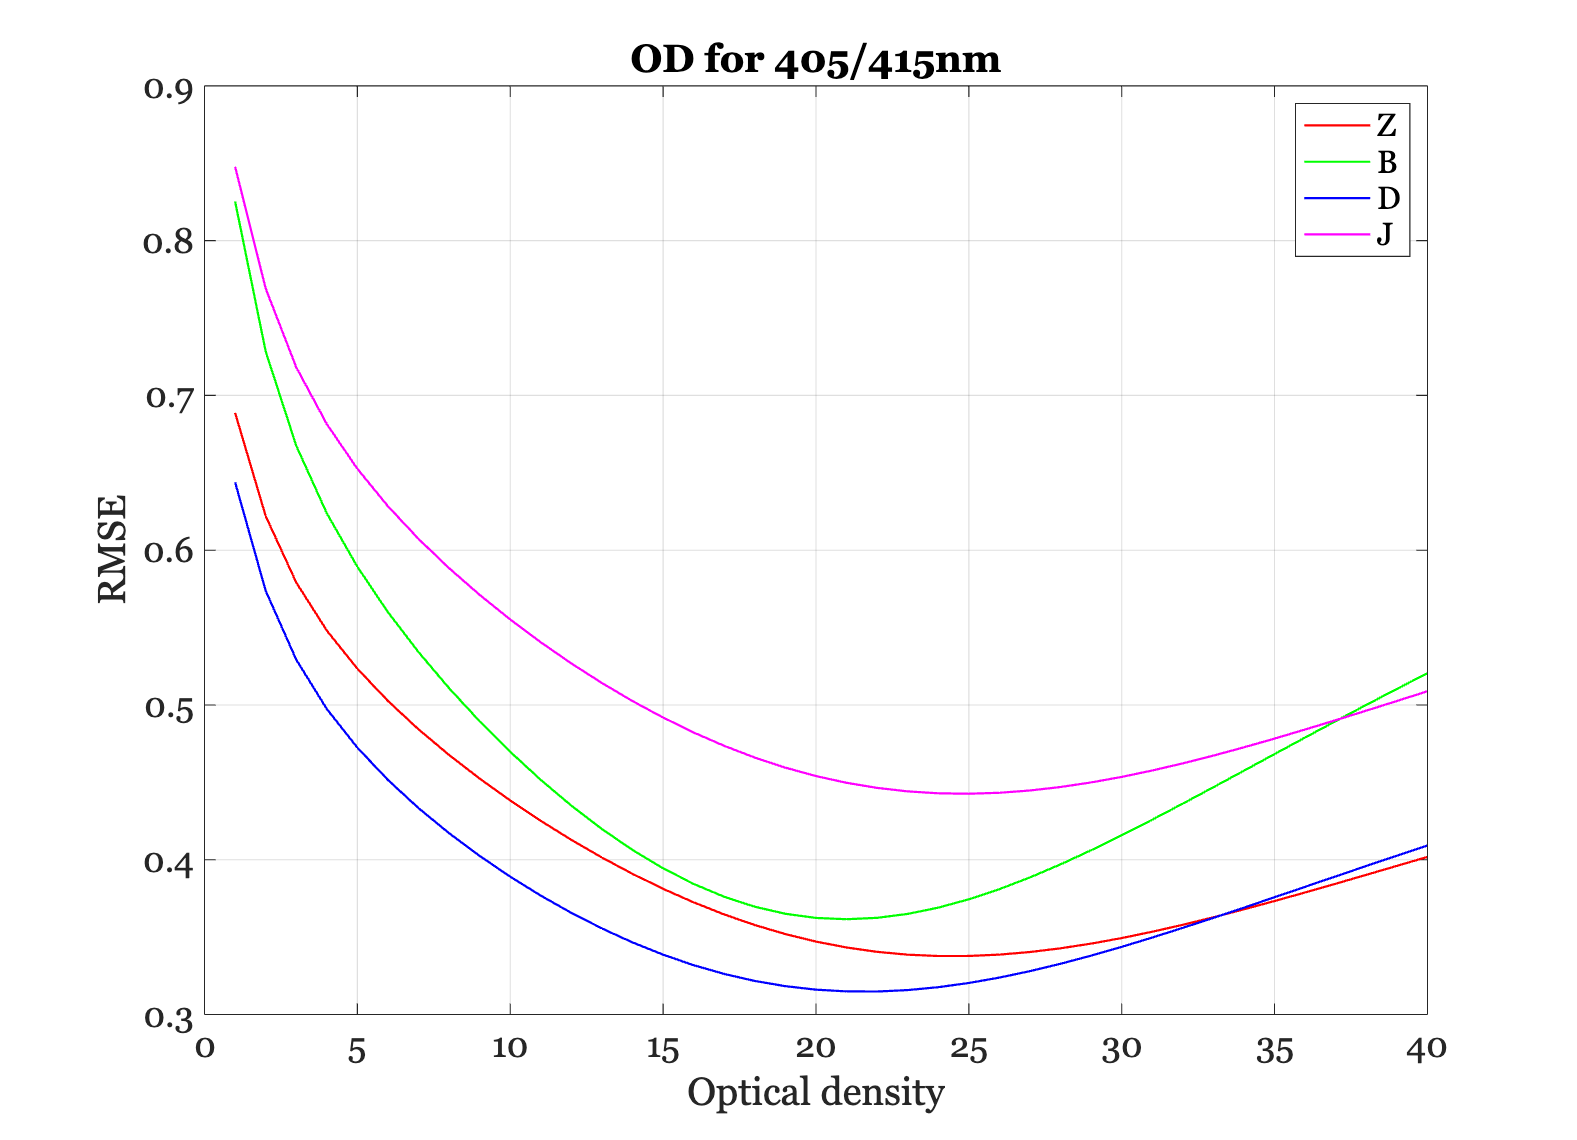


% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the proper optical density and plot

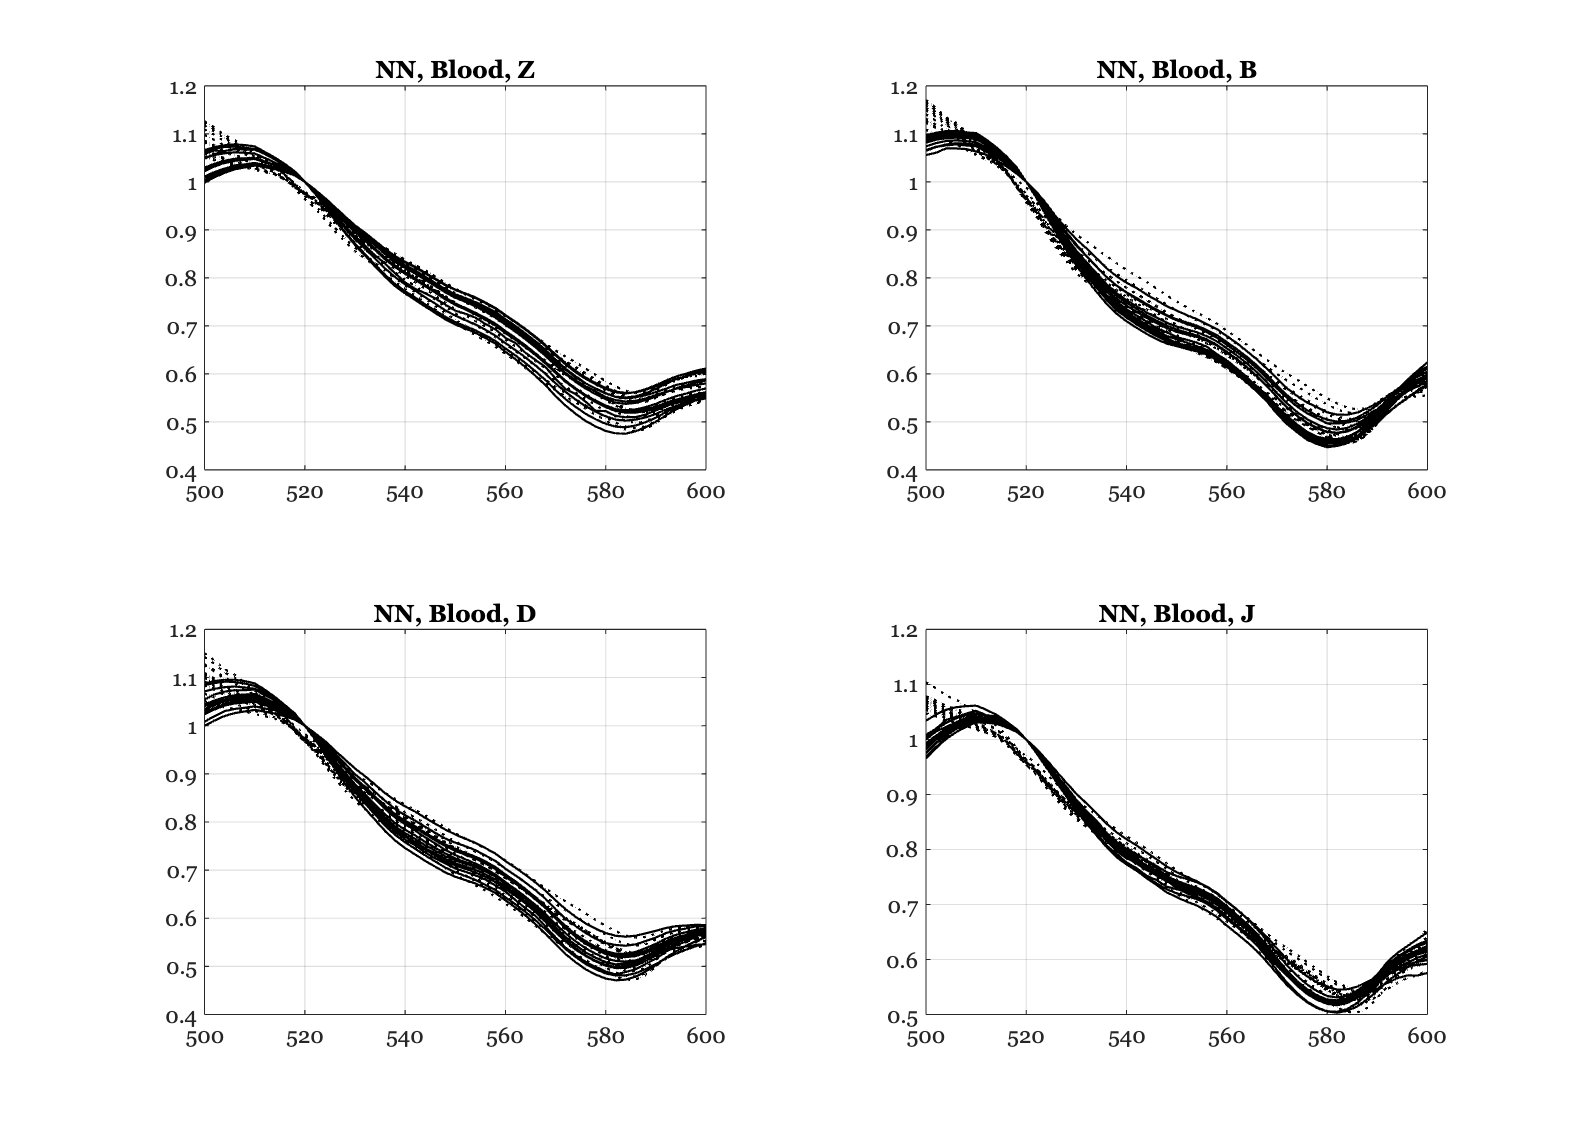

Subject Z
    7.4482    7.4074    6.8302    8.1503    7.3566    6.8962    7.0578    6.8511    6.8301    6.5409    7.6561    8.1359    5.9545    6.2635    6.2129
    1.0685    1.0467    1.0274    1.0826    0.9003    0.9547    0.9090    0.9971    0.9421    0.9548    0.9160    1.0837    1.0241    1.0114    1.0129
    0.4392    0.4539    0.4713    0.4218    0.5358    0.5052    0.5348    0.4811    0.5162    0.5089    0.5227    0.4142    0.4747    0.4777    0.4773

Subject B
   10.8422    8.1251    9.3089   12.6561   10.9606   11.3533   10.5329   12.1564   10.4997   11.1307   10.2316    9.8017    8.5916    9.7103    6.2129
    1.0060    0.9755    0.9816    1.0194    1.0370    1.0552    1.0738    1.0173    1.0370    1.0502    1.0727    1.0190    1.0104    0.9987    1.0129
    0.4164    0.4674    0.4489    0.3812    0.3920    0.3761    0.3755    0.3889    0.3968    0.3817    0.3793    0.4171    0.4391    0.4293    0.4773

Subject D
    8.2754    8.6125    9.2369    7.0054    6.6633    7.1176  

wgtsNN = zeros(size(fluorophoresB,2),size(tongueData,2));

ieFigure;
tiledlayout(2,2);

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNames,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end
    
    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

## Create 450 nm blood optical density levels

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','tongue',...
        'e wave',450);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNames,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 31.00
OD across subjects for 405/415nm 28.00
OD across subjects for 405/415nm 26.00
OD across subjects for 405/415nm 33.00


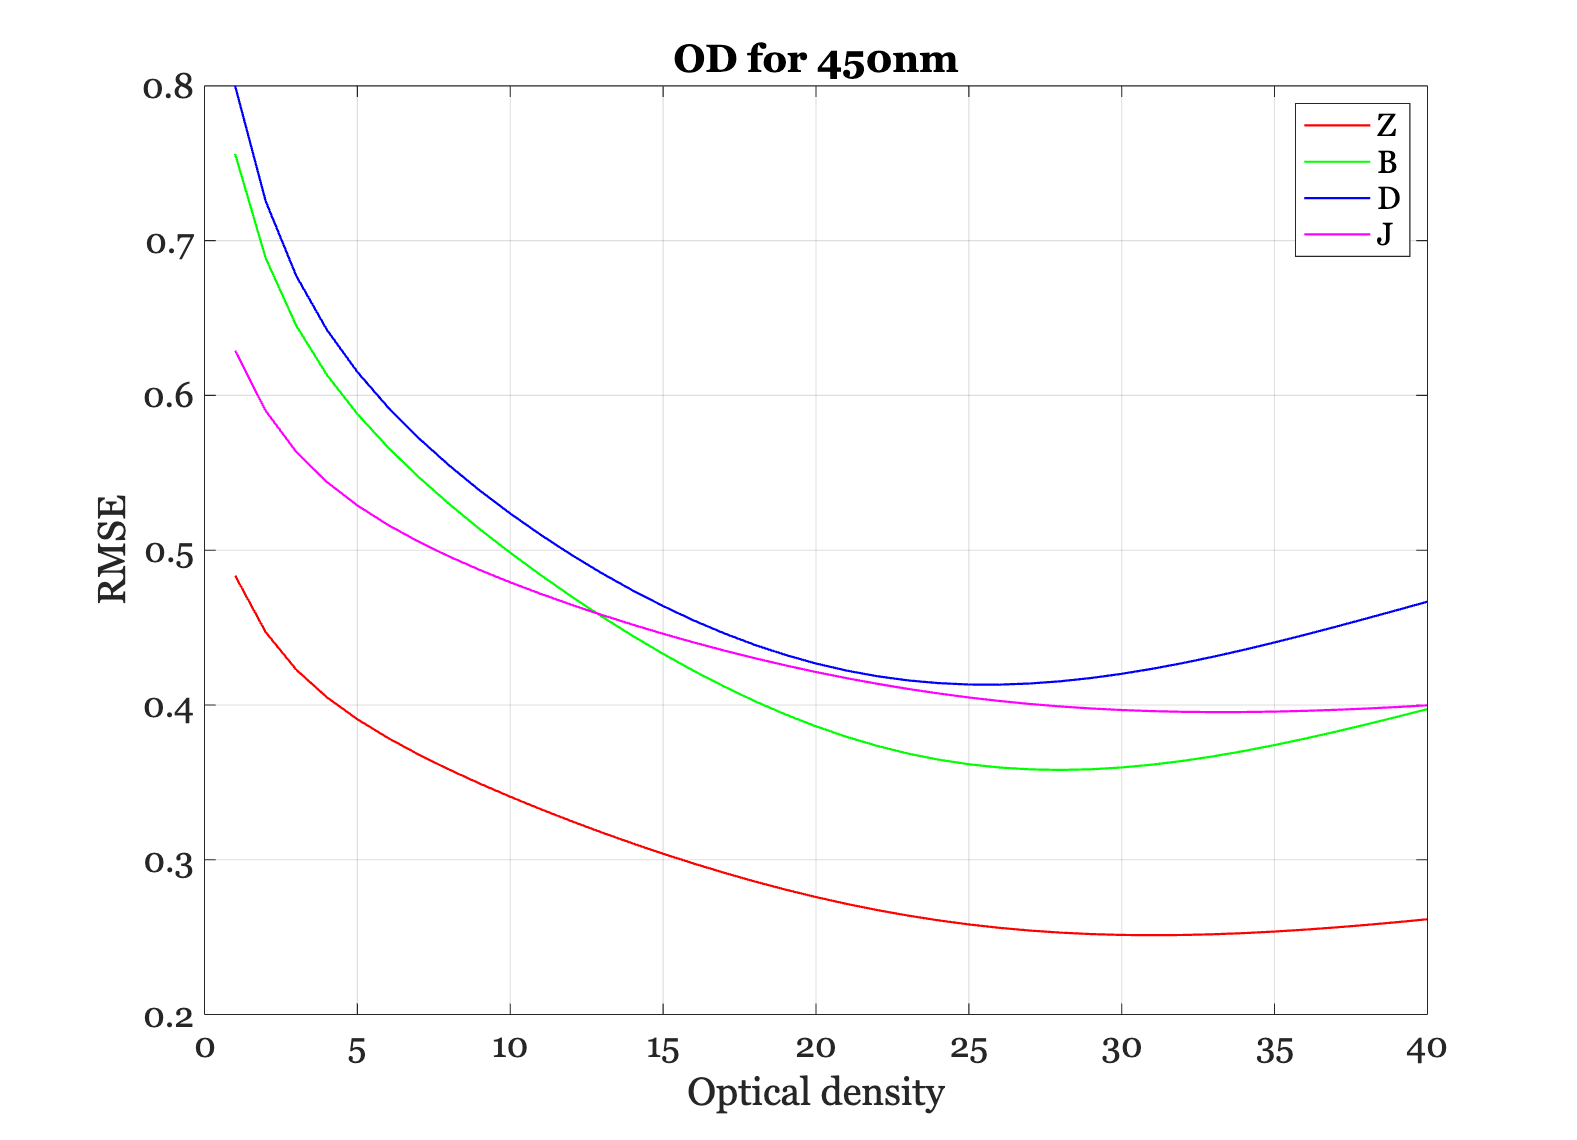



% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## 450 nm excitation light

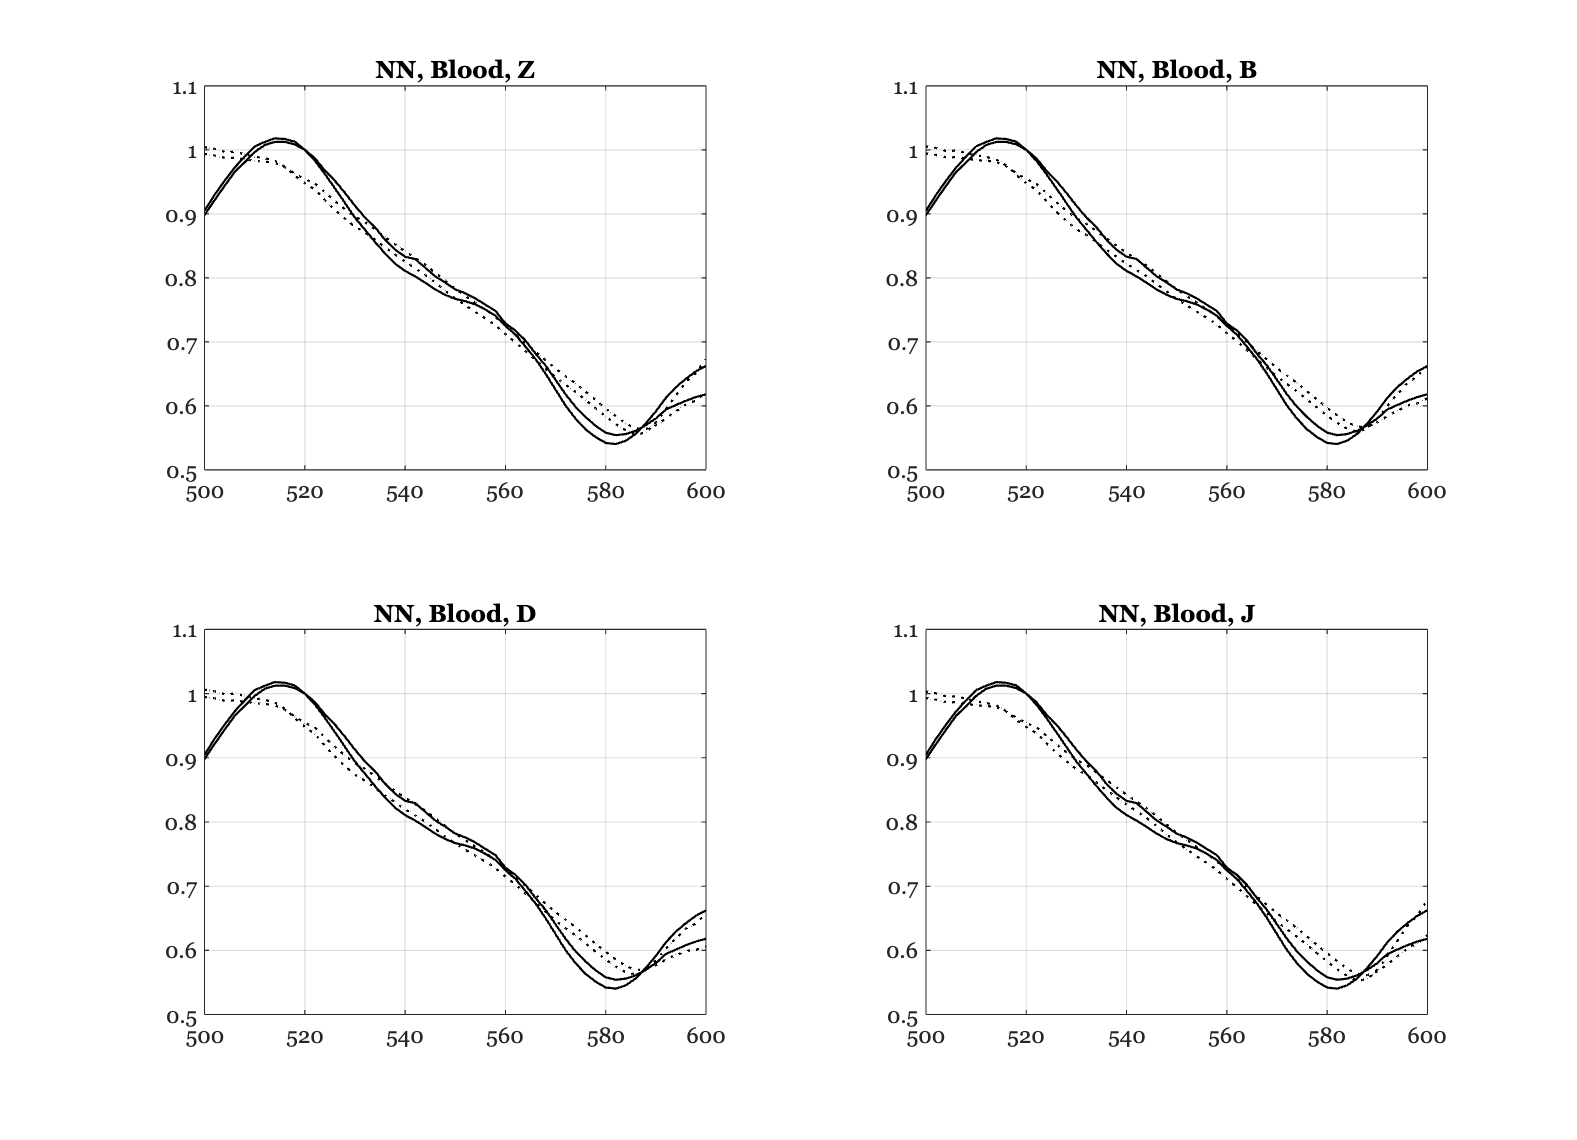

Subject Z
   11.8022    8.2117
    0.8527    0.8621
    0.5420    0.5551

Subject B
   10.7045    7.4104
    0.8284    0.8456
    0.5467    0.5583

Subject D
    9.9758    6.8809
    0.8106    0.8335
    0.5500    0.5606

Subject J
   12.5324    8.7467
    0.8670    0.8721
    0.5392    0.5531



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNames,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end